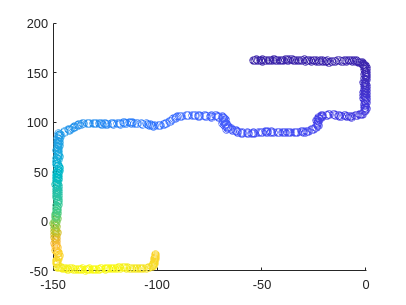

% T = gpslog1;
% lat = T.Lat ./ 1e7
% lon = T.Lon ./ 1e7
% veln = T.VelN ./1e3
% vele = T.VelE ./1e3
% 
% 
% 
% gx = geoaxes;
% geoscatter(gx,lat, lon, 'R','LineWidth',0.2)
% geobasemap(gx,'satellite')
% %axesm('MapProjection','mercator','MapLatLimit',[32.982 32.987],'MapLonLimit',[-96.752 -96.746])
% %axesm('eqaconic','MapLatLimit',[30 60],'MapLonLimit',[-10 10])
% framem; 
% %plotm(lat,lon)
% deltalat = [5 5]; 
% deltalon = [3 3];
% quiverm(lat,lon,veln,vele,'r')
% geoaxes

hold off
K = 5.0;
scatter(report.ukf_x,report.ukf_y,[],report.error)

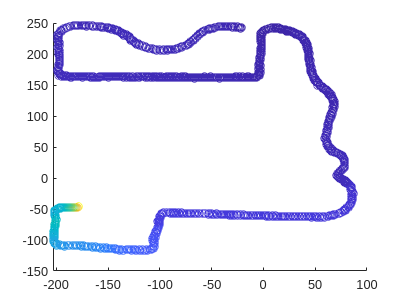

scatter(report_full.ukf_x,report_full.ukf_y,[],report_full.error)

% scatter(report.tru_x,report.tru_y)
% plot(report_full.time, report_full.error,':', 'LineWidth',2)
% hold on
% plot(report_full.time, report_full2.error,':', 'LineWidth',2)
nudge_mean_error = mean(transpose([report_full3_aggr.error, report_full4_aggr.error, report_full5_aggr.error, report_full6_aggr.error]))

nudge_mean_error =        NaN    2.5751    2.5033    2.4518    2.4230    2.4360    2.4536    2.4602    2.4526    2.4519    2.4411    2.4647    2.4585    2.4644    2.4673    2.4773    2.4907    2.4800    2.4791    2.4625    2.4549    2.4649    2.4650    2.4516    2.4302    2.4128    2.4198    2.4116    2.4019    2.3959    2.3944    2.4003    2.4073    2.4073    2.4115    2.4157    2.4223    2.4237    2.4242    2.4173    2.4186    2.4265    2.4220    2.4242    2.4165    2.4092    2.4095    2.4074    2.4061    2.3999


plot(report_full.time, nudge_mean_error,'LineWidth',4,'Color','b')
hold on
nonudge_mean_error = mean(transpose([report_nonudge.error,report_nonudge_2.error,report_nonudge_3.error]))

nonudge_mean_error =     2.7294    2.7003    2.6657    2.7040    2.7138    2.6851    2.6756    2.6817    2.6844    2.6817    2.6886    2.6895    2.6957    2.7009    2.6977    2.7012    2.7027    2.7049    2.6949    2.6945    2.6963    2.6926    2.6933    2.7005    2.6975    2.7006    2.6997    2.7070    2.7102    2.6999    2.6921    2.6989    2.7019    2.7079    2.7073    2.6992    2.7048    2.7055    2.7079    2.7077    2.7082    2.7085    2.7087    2.7065    2.7073    2.7063    2.7096    2.7107    2.7153    2.7149


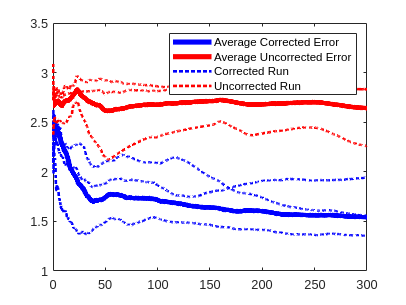

plot(report_full.time, nonudge_mean_error,'LineWidth',4,'Color','r')
hold on
plot(report_full.time, report_full4_aggr.error,':', 'LineWidth',2,'Color','b')
plot(report_full.time, report_nonudge.error,':', 'LineWidth',2,'Color','r')
plot(report_full.time, report_full5_aggr.error,':', 'LineWidth',2,'Color','b')
plot(report_full.time, report_full6_aggr.error,':', 'LineWidth',2,'Color','b')

plot(report_full.time, report_nonudge_2.error,':', 'LineWidth',2,'Color','r')
plot(report_full.time, report_nonudge_3.error,':', 'LineWidth',2,'Color','r')


legend("Average Corrected Error","Average Uncorrected Error","Corrected Run", "Uncorrected Run")

hold off

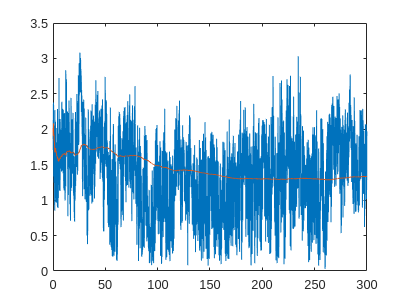

plot(report_full7_detailed.time, report_full7_detailed.current_error)
hold on
plot(report_full7_detailed.time, report_full7_detailed.error)